## Assignment 4 - Pan-Tompkins Algorithm for QRS Detection

## **Assignment Description**

**Learning outcomes** After this assignment, student can detect QRS complexes in ECG signal using the Pan–Tompkins algorithm

**Required reading** Read chapter 4.3.2 "The Pan-Tompkins algorithm for QRS detection" from the [course book](https://oula.finna.fi/Record/oula.1504356).

**Assignment description** Your task is to implement the digital filters required and to apply them on the data to implement the Pan–Tompkins algorithm. You will be supplied a ready-made QRS detector function that operates of the data you have correctly filtered.

## **Problem Summary**

### Introduction

The Pan-Tompkins algorithm identifies QRS complexes (see Fig. 1) based on analysis of the slope, amplitude and width of the QRS. The various stages of the algorithm are shown in Fig. 2.

 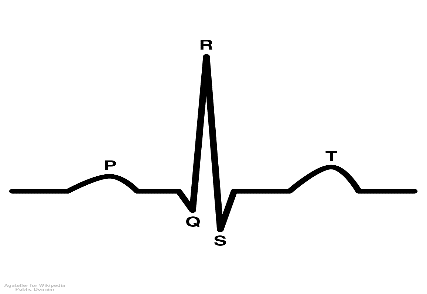

**Figure 1.Schematic representation of normal ECG**

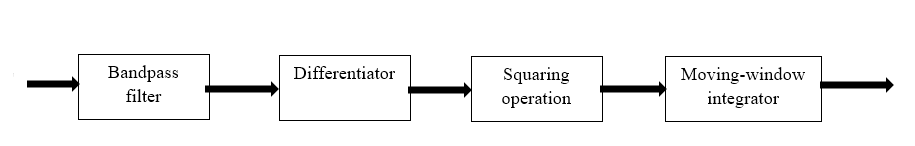

**Figure 2. Block diagram of the Pan-Tompkins algorithm**

The bandpass ﬁlter, formed using lowpass and highpass ﬁlters, reduces noise (such as muscle noise, 60 Hz interference and baseline drift) in the ECG signal. After that, the signal is passed through a diﬀerentiator to provide a large response at the high slopes that distinguish QRS complexes from low-frequency ECG components such as the P and T waves.

The next operation is the squaring operation, which emphasizes the higher values expected within QRS complexes and suppresses smaller values related to the P and T waves among noise in the output of the preceding stage. The squared signal is then passed through a moving-window integrator of window length N = 30 samples (for the sampling frequency of FS = 200 Hz). The expected result is a single smooth peak related to the QRS complex for each ECG cycle. The output of the moving-window integrator may be used to detect QRS complexes, measure RR intervals, and determine the duration of the QRS complex (see Fig. 3).

Read Section 4.3.2 of the [course book](https://oula.finna.fi/Record/oula.1504356?lng=en-gb) for more details. The eBook is accessible within the university network, which you can also reach remotely with [VPN](https://sa.oulu.fi).

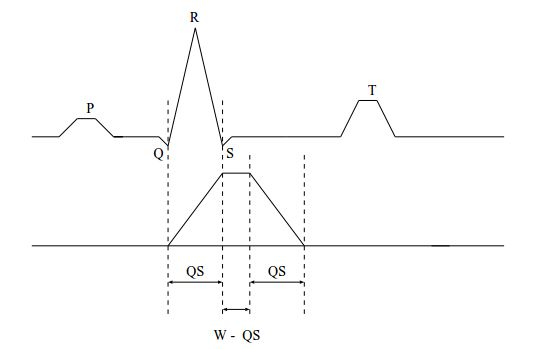

**Figure 3. The relationship between a QRS complex and the moving-window integrator output**

**Data**

The data file `ECG.txt` contains the input ECG sampled at 200 Hz rate. For the task, you are also supplied with a black box function named `findQRS` that finds the beginning and endings of the QRS complexes when supplied with the filtered signals, and detection thresholds. 

**Useful MATLAB commands**

`filter, ones`

### `Task`

Fill in the missing parts of the script to perform various filtering procedures that compose the Pan-Tompkins algorithm. Use the filter function for each step of signal processing; see Section 4.3.2 of the course book about details of the algorithm. ***Note:***Yes, you need to read the chapter from the book at this point.

All the transfer functions of the filters are given in the course book. Before applying them with *filter* command, put them in the following format to get the coefficients *a* and *b*:

Y(z)=b(1)+b(2)z−1+⋯+b(m+1)z−m1+a(2)z−1+⋯+a(n+1)z−nX(z) (1)

The amplitude of an ECG signal may start with a value other than zero. Consequently, the differentiator in the Pan-Tompkins algorithm will amplify the initial step, possibly resulting in an erroneous beat detection. In order to prevent this problem, we will subtract the value of its first sample from the entire ECG signal prior to processing by the Pan-Tompkins algorithm.

You will need to accomplish the following steps:

- Load the data and calculate the sample time

- Subtract the value of the first sample of the ECG signal from the entire ECG

- Low pass filter, equation 4.7

- High pass filter, equation 4.11

- Derivative filter (Notice: Formula 4.14 in the course book (2015, formula 4.13 2002) is incorrect! Correct formula: y(n)=18[x(n)+2x(n−1)−2x(n−3)−x(n−4)].)

- Squaring and integration, formula 4.15 (2015, formula 4.14 2002), N = 30

- Detecting the QRS complexes using the provided `findQRS` blackbox function. Use blanking interval of *250 ms*, and the detection thresholds given in the code template

- Calculate the combined filtering delay

`The findQRS `function call syntax is as follows:` [QRSStart, QRSEnd] = findQRS(data,blankingInterval,treshold1,treshold2) `where

Inputs:

- `data`: P-T output from which you want to detect the QRS complexes (point 6. above)

- `blankingInterval`: number of samples not processed after a QRS complex found, i.e. new start of QRS is not allowed within this distance from previous hit

- `treshold1`: Q-wave begins here

- `treshold2`: S-wave

Outputs:

- `QRSStart`: beginning points of QRS complexes

- `QRSEnd`: ending points of QRS complexes

% The sampling rate is 200 Hz 
FS = 200;

% Calculate the sample interval from FS
T = 1/FS

T = 0.0050


% Load the ECG from the file 'ECG.txt'
ECG = load('ECG.txt')

ECG =         1941
        1939
        1944
        1980
        1995
        2010
        2024
        2024
        2037
        2068



% Substract the first sample value to prevent P-T to amplify inital step
ECG = ECG - ECG(1)

ECG =      0
    -2
     3
    39
    54
    69
    83
    83
    96
   127



% Lowpass filter The ECG
b_lowpass = (1/32)*[1 zeros(1, 5) -2 zeros(1,5) 1]

b_lowpass =     0.0312         0         0         0         0         0   -0.0625         0         0         0         0         0    0.0312


a_lowpass = [1 -2 1]

a_lowpass =      1    -2     1


ECG_filtered1 = filter(b_lowpass, a_lowpass, ECG)

ECG_filtered1 =          0
   -0.0625
   -0.0312
    1.2188
    4.1562
    9.2500
   16.9375
   27.3438
   40.5625
   55.3125



% Highpass filter the lowpass filtered ECG
b_highpass = (1/32)*[-1 zeros(1, 15) 32 -32 zeros(1, 14) 1]

b_highpass =    -0.0312         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.0000   -1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0312


a_highpass = [1 -1]

a_highpass =      1    -1


ECG_filtered2 = filter(b_highpass, a_highpass, ECG_filtered1)

ECG_filtered2 =          0
    0.0020
    0.0029
   -0.0352
   -0.1650
   -0.4541
   -0.9834
   -1.8379
   -3.1055
   -4.8340



% Differential filter the high- and lowpass filtered ECG
b_diff = (1/8)* [1 2 0 -2 -1]

b_diff =     0.1250    0.2500         0   -0.2500   -0.1250


a_diff = 1

a_diff = 1

ECG_filtered3 = filter(b_diff, a_diff, ECG_filtered2)

ECG_filtered3 =          0
    0.0002
    0.0009
   -0.0037
   -0.0299
   -0.0990
   -0.2280
   -0.4299
   -0.7135
   -1.0780



% Square the derivative filtered signal
ECG_filtered4 = ECG_filtered3.^2

ECG_filtered4 = 1.0e+04 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001



% Moving window integrator filter the squared signal
% Window size
N = 30;
b_integ = (1/N)*ones(1,N)

b_integ =     0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333


a_integ = 1

a_integ = 1

ECG_filtered5 = filter(b_integ, a_integ, ECG_filtered4)

ECG_filtered5 = 1.0e+03 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001



% Set the blanking interval to 250 ms, but convert it to samples for the findQRS function
blankingInterval = 0.250/T

blankingInterval = 50


% The amplitude threshold for QRS detection are set to these
treshold1 = 500; 
treshold2 = 2650; 

% Call the findQRS function 
[QRSStart_ECG, QRSEnd_ECG] = findQRS(ECG_filtered5, blankingInterval, treshold1, treshold2)

QRSStart_ECG =           50         177         302         427         551         676         801         924        1049        1176        1303        1435        1566        1694        1821        1950


QRSEnd_ECG =           59         188         314         437         561         686         811         934        1060        1186        1313        1444        1575        1702        1829        1959



% Calculate the cumulative filter delays (in samples)
delay_bpf = (0.025 + 0.080) * FS

delay_bpf = 21.0000

delay_diff = - (5 - 1)

delay_diff = -4

delay_int = N - 1

delay_int = 29

delays = delay_bpf + delay_diff + delay_int

delays = 46

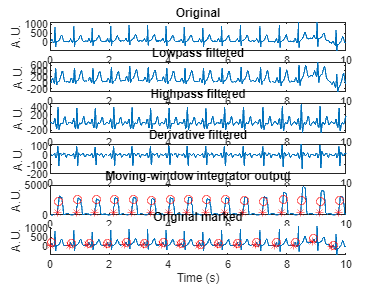

# beats: 16
avg R-R: 633.3333
std R-R: 12.6303
HR bpm : 94.7368


%delays = QRSEnd_ECG - QRSStart_ECG % (0.025 + 0.080) * FS + N - 1 * ones(length(QRSStart_ECG), 1)

visualize_qrs(T, ECG, ECG_filtered1, ECG_filtered2, ECG_filtered3, ECG_filtered5, QRSStart_ECG, QRSEnd_ECG, delays)

delay = mean(grpdelay(firf))